clear
targetImage = im2double(imread("dogdogorange.png"));
imagefiles = dir("data64\test\animal animal_faces cat cat_face\*.jpg")

imagefiles = 1650×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


filepath = "data64\test\animal animal_faces cat cat_face"

filepath = "data64\test\animal animal_faces cat cat_face"


rTileSize = 64;
oTileSize = 8;

[rows, cols, ~] = size(targetImage)

rows = 867

cols = 701

tileRows = ceil(rows / oTileSize)

tileRows = 109

tileCols = ceil(cols / oTileSize)

tileCols = 88

numberOfTiles = tileRows * tileCols;
averageWantedColours = zeros(numberOfTiles, 3);
counter = 1

counter = 1

for c = 1:tileCols
    for r = 1:tileRows
        tileRFrom = 1 + (r-1)*(oTileSize);
        tileRTo = r*oTileSize;
        if tileRTo > rows
            tileRTo = rows;
        end
        tileCFrom = 1 + (c-1)*(oTileSize);
        tileCTo = c*oTileSize;
        if tileCTo > cols
            tileCTo = cols;
        end
        currentTile = targetImage(tileRFrom:tileRTo, tileCFrom:tileCTo, :);

        averageWantedColours(counter,:) = averageColourXYZ(currentTile);
        
        counter = counter + 1;
    end
end

averageWantedColours

averageWantedColours =    61.9750   64.0393   60.1534
   62.1552   64.0793   59.4562
   62.2921   64.3844   60.0816
   62.2194   64.1979   60.4667
   62.0279   63.9644   60.1999
   62.1765   64.2333   59.9310
   62.3437   64.2000   60.6170
   62.1466   64.2649   60.3154
   62.8312   65.3158   61.4268
   64.0211   66.3191   61.8765



for ii=1:1650
   currentfilename = imagefiles(ii).name;
   currentimage = im2double(imread(filepath + "\" +  currentfilename));
   images{ii} = currentimage;
end

[~, numberOfImages] = size(images);
threshold = 0.7;
threshold2 = 17;
imagesFiltered = {};
for image = 1:numberOfImages
    imageAdded = false;
    %convert to XYZ
    currentImageXYZ = averageColourXYZ(images{image});
    for tile = 1:numberOfTiles
        if imageAdded
            break
        end

        % use calcDeltaE
        [meanDeltaE, ~] = calcDeltaE(averageWantedColours(tile,:), currentImageXYZ');
        % if the image could be useful add it
        if meanDeltaE < threshold
            % check vs added images
            [~, numberOfAddedImages] = size(imagesFiltered);
            if numberOfAddedImages == 0
                imagesFiltered{end+1} = images{image};
                imageAdded = true;
                continue
            end

            for addedImageIndex = 1:numberOfAddedImages
                addedImage = imagesFiltered{addedImageIndex};
                colourAverageAdded = averageColourXYZ(addedImage);
                [meanDeltaE2, ~] = calcDeltaE(colourAverageAdded', currentImageXYZ');
                if meanDeltaE2 > threshold2
                    imagesFiltered{end+1} = images{image};
                    imageAdded = true;
                    break;
                end
            end
            
            
        end
    end
end

imagesFiltered

imagesFiltered = 1×882 cell array
    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {6

processedImages = imagesFiltered

processedImages = 1×882 cell array
    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {

%processedImages = preprocessImages(imagesFiltered, 12);
[~, datasetSize] = size(processedImages)

datasetSize = 882

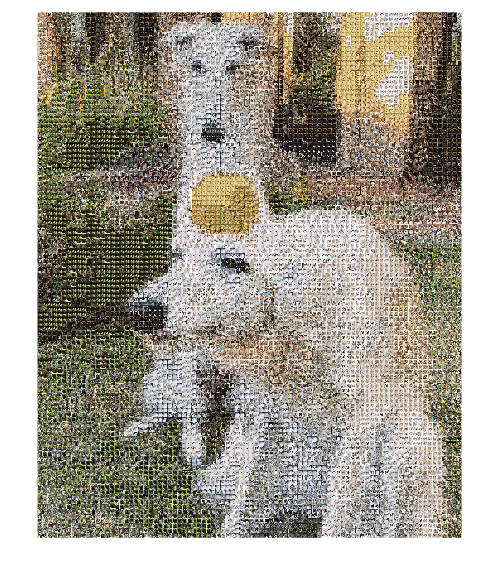

processbar = waitbar(0, 'Processing Images...');
% go through each tile
for c = 1:tileCols
    for r = 1:tileRows
        tileRFrom = 1 + (r-1)*(oTileSize);
        tileRTo = r*oTileSize;
        if tileRTo > rows
            tileRTo = rows;
        end
        tileCFrom = 1 + (c-1)*(oTileSize);
        tileCTo = c*oTileSize;
        if tileCTo > cols
            tileCTo = cols;
        end
        currentTile = targetImage(tileRFrom:tileRTo, tileCFrom:tileCTo, :);

        % convert current Tile to xyz, might use average colour
        averageTileXYZ = averageColourXYZ(currentTile);

        
        bestImageIndex = 0;
        bestDeltaE = 1000;

        waitbar(c/tileCols, processbar, "bonking kitties...");

        % find best image for each tile
        for i = 1:datasetSize
            
            curImg = processedImages{i};
            % convert current sample image to xyz

            %imshow(curImg)
            currentImageXYZ = averageColourXYZ(curImg);


            % use calcDeltaE
            [meanDeltaE, Max] = calcDeltaE(averageTileXYZ', currentImageXYZ');
            randRange = 2;
            Max = Max + (rand * 2 * randRange - randRange);

            if Max < bestDeltaE
                bestDeltaE = Max;
                bestImageIndex = i;
            end


            averageTileXYZ;
            currentImageXYZ;
            Max;
            i;
            bestImageIndex;

        end
        tileRFrom = 1 + (r-1)*(rTileSize);
        tileRTo = r*rTileSize;
        tileCFrom = 1 + (c-1)*(rTileSize);
        tileCTo = c*rTileSize;
        outputImage(tileRFrom:tileRTo, tileCFrom:tileCTo, :) = processedImages{bestImageIndex};
    end
end
close(processbar)

imshow(outputImage)